clear
clc
close all
% 弹体气动数据
V = 914.4;
a1 = 1.5;
a2 = 250;
a3 = 280;
a4 = 1.6;
a5 = 0.23;

kv = V/(57.3*9.8);
% 过载闭环传递函数

A1 = a1+a4;
A2 = a2+a1*a4;

omega_n = 13.83;
omega_n1 = 22.14;
epsilon = 0.6;

N2 = omega_n1+2*epsilon*omega_n-A1;
N1 = omega_n^2+2*epsilon*omega_n*omega_n1-A2;
N0 = omega_n^2*omega_n1;

omega_a = a4-a2*a5/a3;
KAC_Kg_kv =  -(omega_n^2*omega_n1)/(a3*a4-a2*a5)

KAC_Kg_kv = -10.8658

KA_omegai_KR = (omega_n1*omega_n^2/omega_a-(omega_n^2+2*epsilon*omega_n*omega_n1-A2-(omega_n1+2*epsilon*omega_n-A1)*omega_a))/((-a3+a5*(omega_a-a1))*kv);


G_ny_nye = tf(KAC_Kg_kv.*[a5 a1*a5 -(a3*a4-a2*a5)], [1 A1+N2 A2+N1 N0])

G_ny_nye =
 
    -2.499 s^2 - 3.749 s + 4243
  --------------------------------
  s^3 + 38.74 s^2 + 559.5 s + 4243
 
连续时间传递函数。
模型属性



step(G_ny_nye)

omega_n = 11.91;
omega_n1 = 29.85;
epsilon = 0.6;

N2 = omega_n1+2*epsilon*omega_n-A1;
N1 = omega_n^2+2*epsilon*omega_n*omega_n1-A2;
N0 = omega_n^2*omega_n1;

omega_a = a4-a2*a5/a3;
KA_omegai_KR = (omega_n1*omega_n^2/omega_a-(omega_n^2+2*epsilon*omega_n*omega_n1-A2-(omega_n1+2*epsilon*omega_n-A1)*omega_a))/((-a3+a5*(omega_a-a1))*kv);
KAC_Kg_kv =  -(omega_n^2*omega_n1)/(a3*a4-a2*a5)

KAC_Kg_kv = -10.8429


G_ny_nye = tf(KAC_Kg_kv.*[a5 a1*a5 -(a3*a4-a2*a5)], [1 A1+N2 A2+N1 N0])

G_ny_nye =
 
    -2.494 s^2 - 3.741 s + 4234
  --------------------------------
  s^3 + 44.14 s^2 + 568.5 s + 4234
 
连续时间传递函数。
模型属性



hold on
step(G_ny_nye)

omega_n = 10.77;
omega_n1 = 36.55;
epsilon = 0.6;

N2 = omega_n1+2*epsilon*omega_n-A1;
N1 = omega_n^2+2*epsilon*omega_n*omega_n1-A2;
N0 = omega_n^2*omega_n1;

omega_a = a4-a2*a5/a3;
KA_omegai_KR = (omega_n1*omega_n^2/omega_a-(omega_n^2+2*epsilon*omega_n*omega_n1-A2-(omega_n1+2*epsilon*omega_n-A1)*omega_a))/((-a3+a5*(omega_a-a1))*kv);
KAC_Kg_kv =  -(omega_n^2*omega_n1)/(a3*a4-a2*a5)

KAC_Kg_kv = -10.8567


G_ny_nye = tf(KAC_Kg_kv.*[a5 a1*a5 -(a3*a4-a2*a5)], [1 A1+N2 A2+N1 N0])

G_ny_nye =
 
    -2.497 s^2 - 3.746 s + 4240
  --------------------------------
  s^3 + 49.47 s^2 + 588.4 s + 4240
 
连续时间传递函数。
模型属性



hold on
step(G_ny_nye)

omega_n = 8.3;
omega_n1 = 44.32;
epsilon = 0.6;

N2 = omega_n1+2*epsilon*omega_n-A1;
N1 = omega_n^2+2*epsilon*omega_n*omega_n1-A2;
N0 = omega_n^2*omega_n1;

omega_a = a4-a2*a5/a3;
KA_omegai_KR = (omega_n1*omega_n^2/omega_a-(omega_n^2+2*epsilon*omega_n*omega_n1-A2-(omega_n1+2*epsilon*omega_n-A1)*omega_a))/((-a3+a5*(omega_a-a1))*kv);
KAC_Kg_kv =  -(omega_n^2*omega_n1)/(a3*a4-a2*a5)

KAC_Kg_kv = -7.8187


G_ny_nye = tf(KAC_Kg_kv.*[a5 a1*a5 -(a3*a4-a2*a5)], [1 A1+N2 A2+N1 N0])

G_ny_nye =
 
    -1.798 s^2 - 2.697 s + 3053
  --------------------------------
  s^3 + 54.28 s^2 + 510.3 s + 3053
 
连续时间传递函数。
模型属性


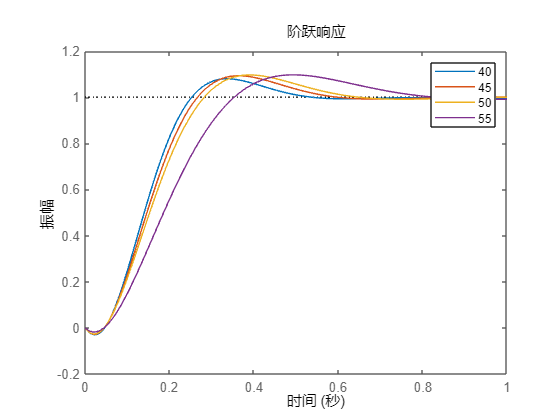


hold on
step(G_ny_nye)
legend('40','45','50','55')